# **MATLAB TUTORIAL 2:**

# **PROGRAMMING IN MATLAB**

Please complete the following problems in this Livescript unless otherwise indicated. Remember to create a folder with the name Tutorial2_username (e.g. if your username is abc, then Tutorial2_abc) to put all the files and figures related to the Tutorial (including this Livescript). When you are finished, zip the folder and upload it to the BlackBoard Assignment submission box. 

Write the scripts and save them for later reuse. If you run into problems, read about debugging strategies (in the lecture notes).

### 2.1 Create a program “welcome” that greets the world.

Your program should display the string “Hello world!” on execution. Do not forget to add some comments to the program, describing what the program does, when it was created, and by whom. Use the disp() function.

(This is a trivial ﬁrst example of a program, it will be short!)

Write the program.

[Hint: even if it is short and trivial, write the script in its own .m file.]

Run the program as a new command from the command line in the box below.

Run the program from the command line with the run-command.

Run the program with the button in the tool bar.

Show the program (and the runs) to your tutor.

% Run your program here

disp('Hello_World!')

Hello_World!


edit ('Hello_World.m')

### 2.2 Throwing two dice

Write a program that prints the score for each dice and the sum of the scores. Create random real numbers (check the Matlab help) between zero and one, multiply the number by six, and round them up to the nearest integer.

Write a program with header and comments.

Run the program (manually) several times an paste all outputs to a text ﬁle.

A = randi ([1,6],1,2)  %get a random number between 1 and 6

A =      3     5


       
SUM = A(1)+A(2)    %sum of two results

SUM = 8

### 2.3 Hydrostatics: Draught of a ﬂoating cuboid

A cuboid of length l, width w and height h is made of a material of a density $\rho_c$ that is smaller than the density of the surrounding ﬂuid $\rho_{fluid}$. The cuboid is assumed to ﬂoat stably. Write a program that computes the draught of the cuboid (the height of the cuboid that remains under water). The program must prompt the user to input l, w, h,  $\rho_c$ and $\rho_{fluid}$. Use the function disp() to print the resulting cuboid volume, mass, submerged volume and the draught. Remember to hide any intermediate outputs using the ;.

Write the program with header and comments. Remember in the assessment, you will get marks for style and clarity!

Show the program and its results to a tutor.

Note: the formula for the submerged volume of a cuboid is $V_{sub}=\frac{mass}{\rho_f}$

and the formula for the draught of a cuboid is  $draught=\frac{V_{sub}}{w   l}$

% Test your code here

run cuboid.m

What is the draught of a surf-board-like cuboid (l = 3m, w = 0.8m, h = 0.1m) made of styro-foam ($\rho_c$ = 10kg/m3) ﬂoating on water ($\rho_{fluid}$ = 1,000kg/m3)?

Answer:

If ﬁnished early:

If the density of the cuboid is greater than the density of the ﬂuid, the cuboid will sink. Add an if-statement to warn the user! Check how to use if statements in the Matlab help

### 2.4 One dimensional arrays

We start out with very simple examples on the use of arrays.

**Basic operations**

Create an array* firstArray* of ﬁve elements “11, 12, 13, 14, 15” by typing in each element individually. (for example A(1)=1, A(2)=2, etc).

Print the array using disp().

Sum up the second and fourth elements.

Multiply the third element with 2.

Swap the ﬁrst and ﬁfth element.

Copy *firstArray* to *copyArray* (elementwise).

A(1) = 11

A =     11     5


A(2) = 12

A =     11    12


A(3) = 13

A =     11    12    13


A(4) = 14

A =     11    12    13    14


A(5) = 15

A =     11    12    13    14    15



firstArray = A

firstArray =     11    12    13    14    15


disp(A) 

    11    12    13    14    15




c = A

c =     11    12    13    14    15



B = A(2) + A(4)

B = 26


A(3) = A(3)*2

A =     11    12    26    14    15



a = A(1)

a = 11

A(1) = A(5)

A =     15    12    26    14    15


A(5) = a

A =     15    12    26    14    11


disp(A)

    15    12    26    14    11




copyArray = c

copyArray =     11    12    13    14    15


**Easier typing**

Create the array *secondArray* with the elements “21, 22, 23, 24, 25, 26” by typing the values in brackets.

Create the array.

Print it on the screen using disp().

secondArray = [21 , 22 , 23 , 24 , 25 , 26]

secondArray =     21    22    23    24    25    26


 
disp(secondArray)

    21    22    23    24    25    26



### 2.5 Two dimensional arrays

Create an array *thirdArra*y with the elements “11, 12, 13” in row one, “21, 22, 23” in row two, and “31, 32, 33” in row three:

11 12 13 21 22 23 31 32 33

Print the array on the screen.

Print elements *thirdArray*(1,3) and *thirdArray*(3,1).

Which index denotes the row, which the column?

Create the variables row=1 and column=3. How would you address the element in the ﬁrst row and third column of *thirdArray* using these variables?

Matlab expression:

Which index is ﬁrst?

Assume that you do not know the size of* thirdArray*.

Use the function size() to determine the array size.

Call size() such that the number of rows and columns are stored in two diﬀerent variables NumberOfRows and NumberOfColumns.

thirdArray = [11 , 12 , 13 ; 21 , 22 , 23 ; 31 , 32 , 33]

thirdArray =     11    12    13
    21    22    23
    31    32    33



disp(thirdArray(3,1))

    31



disp(thirdArray(1,3))

    13




%first number indicated rows, second number(after ,)indicates coloums

var1 = thirdArray(1 , : )

var1 =     11    12    13


var2 = thirdArray(: , 3)

var2 =     13
    23
    33


size(var1)

ans =      1     3


size(var2)

ans =      3     1


**Plotting Data**

To plot data in Matlab use the plot() function, deﬁning the x and y arrays where data to be plotted is stored.

Create the arrays x=[0,1,2,3,4,5,6], y1=[0,1,2,3,4,5,6],

y2=[0,1,4,9,16,25,36] and y3=[0,1,8,27,64,125,216].

Plot y1, y2 and y3 in the same graph over x, using diﬀerent colours and line styles. (Use the Matlab help to ﬁnd out how to use the plot() function. Use the command hold on.)

Save the ﬁle as a ”*.png” or a ”*.pdf” and show it to a tutor.

Plot x as a function of y2.

Plot y3 as a function of y2.

Add three additional points to the arrays x, y1, y2, and y3, extending the series.

Create a new plot of all three arrays. Save it as another ”*.png” or a ”*.pdf”.

x = [0 , 1 , 2 , 3 , 4 , 5 , 6]

x =      0     1     2     3     4     5     6


y1 = x

y1 =      0     1     2     3     4     5     6


y2 = [0 1 4 9 16 25 36 ]

y2 =      0     1     4     9    16    25    36


y3 = [0 1 8 27 64 125 216]

y3 =      0     1     8    27    64   125   216


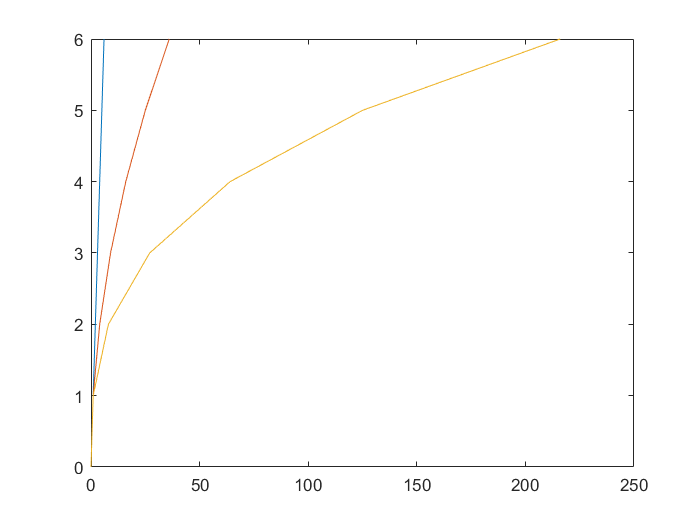


plot(y1,x)
hold on
plot(y2,x)
plot(y3,x)
hold off
saveas(gcf, 'Y1_Y2_Y3_against_x.png')

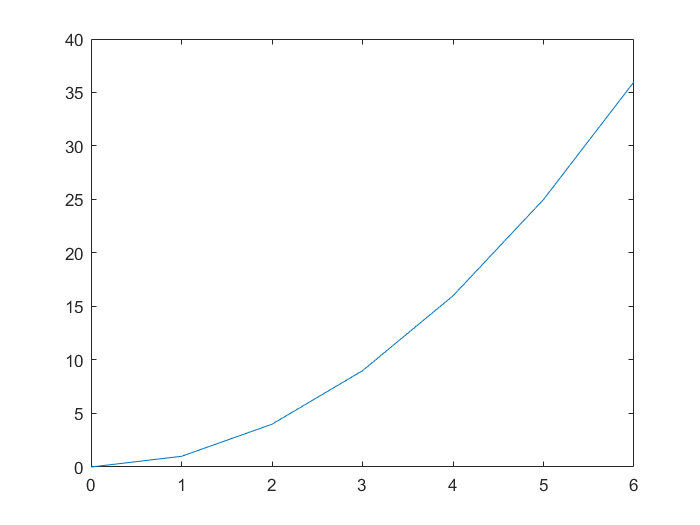


plot(x,y2)

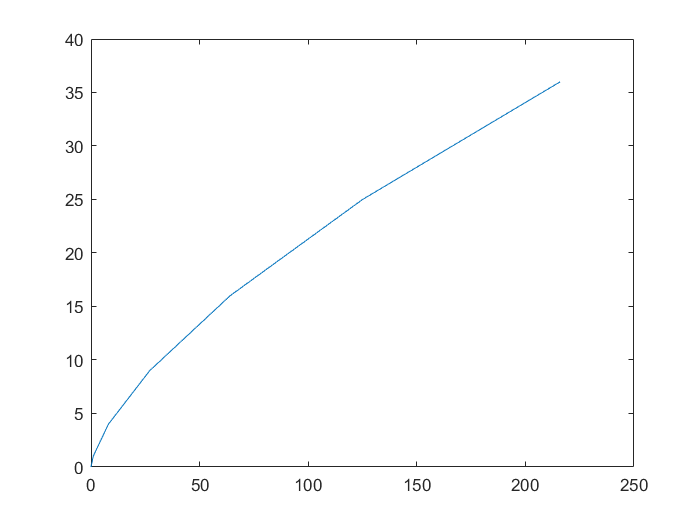

plot(y3,y2)


x = [x , 7 , 8 , 9]

x =      0     1     2     3     4     5     6     7     8     9


y1 = x

y1 =      0     1     2     3     4     5     6     7     8     9


y2 = [y2, 49 , 64 , 81]

y2 =      0     1     4     9    16    25    36    49    64    81


y3 = [y3 , 343 , 512 , 729]

y3 =      0     1     8    27    64   125   216   343   512   729


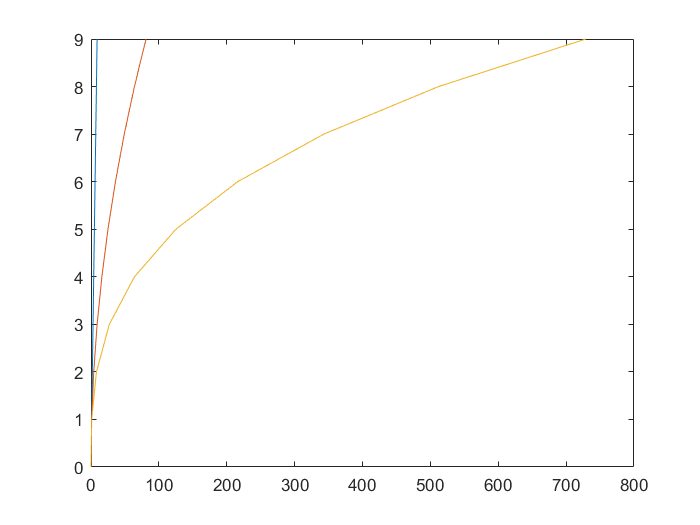


plot(y1,x)
hold on
plot(y2,x)
plot(y3,x)
hold off

saveas(gcf, 'anotherY1_Y2_Y3_against_x.png')

### 2.6  Throwing two dice, revisited (Optional)

In tutorial 2.2, you have written a program that simulates throwing dice. In some games, the total score will be doubled if the score of the ﬁrst dice equals the score of the second dice. Alter your program such that the total score is doubled if both dice show the same score.

run random_dice_result.m

A =      1     1


SUM = 2

SUM = 4